Load data.

clear
load('PowerChargerDataTable.mat')

Plot power usage in traditional charging station.

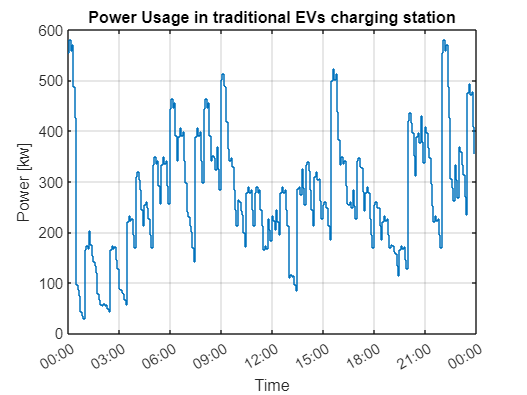

time = ChargerData.timestamp;
totalPower = ChargerData.ChargerPower.TotalkWhs;
totalPower = totalPower*(60*60); % convert kWh/s to kW
stairs(time, totalPower)
title('Power Usage in traditional EVs charging station')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
grid on

Set threshold value to start charge or discharge ESS.

pChgEss = 300;      % Start charging ESS after power usage drop below this value [kW]
pDscEss = 350;      % Start discharge ESS after power usage above this value [kW]

Set Energy capacity [Kwh] and E-rate for ESS. (assume charge and discharge rate is equal)

capa = 500;
Erate = 1;

Set initail and limit SoC of Ess.

soc = 0.28;
soc_min = 0.1;
soc_max = 1;

Set on/off peak time.

onPeakStr  = datetime(2023,11,9,9,0,0);     % on-peak time start from 9.00
offPeakStr = datetime(2023,11,9,22,0,0);    % off-peak time start from 22.00

Determine time step (dt) in seconds.

dt = [time; time(1)] - [time(1); time];
dt = dt(2:end-1);
dt = seconds(mean(dt));

ESS algorithm.

Pev = totalPower';
Pbatt = zeros(1,length(time));
Ebatt = zeros(1,length(time)+1);
Ebatt(1) = capa * soc;
Ebatt_min = capa * soc_min;
Ebatt_max = capa * soc_max;
Pchg_max  = -capa * Erate;
Pdsc_max  = capa * Erate;

for i = 1:length(time)
    if Pev(i) < pChgEss
        % charge
        Pbatt(i) = -(pDscEss-Pev(i));       % ESS using active sign convension
        Pbatt(i) = max(Pbatt(i), Pchg_max); % limit maximum power
        Echg = Pbatt(i)*(dt/3600);
        if (Ebatt(i)-Echg) > Ebatt_max      % battery is full ?
            Echg = -max(0, Ebatt_max-Ebatt(i));
            Pbatt(i) = Echg/(dt/3600);
        else
            if (onPeakStr < time(i)) && (time(i) < offPeakStr) % on-peak period
                Pbatt(i) = 0;
                Echg = 0;
            end
        end
        
        Ebatt(i+1) = Ebatt(i) - Echg;

    elseif Pev(i) > pDscEss
        % discharge
        Pbatt(i) = Pev(i)-pDscEss;
        Pbatt(i) = min(Pbatt(i), Pdsc_max); % limit maximum power
        Edsc = Pbatt(i)*(dt/3600);
        if (Ebatt(i)-Edsc) < Ebatt_min      % battery is deplete ?
            Pbatt(i) = 0;
            Edsc = 0;
        end
        
        Ebatt(i+1) = Ebatt(i) - Edsc;

    else
        Ebatt(i+1) = Ebatt(i);
    end
end

Pgrid = Pev - Pbatt;
soc = Ebatt(2:end)*100/capa;

Plot grid power.

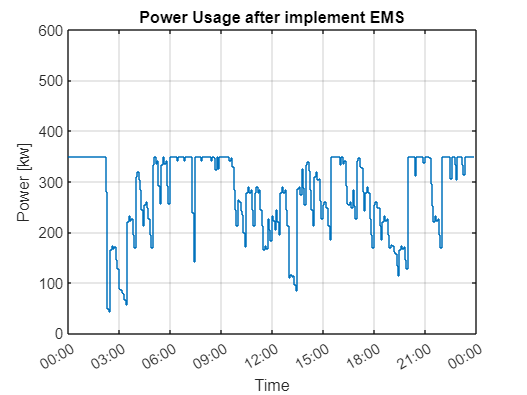

stairs(time, Pgrid)
title('Power Usage after implement EMS')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
ylim([0 600])
grid on

Plot ESS SoC.

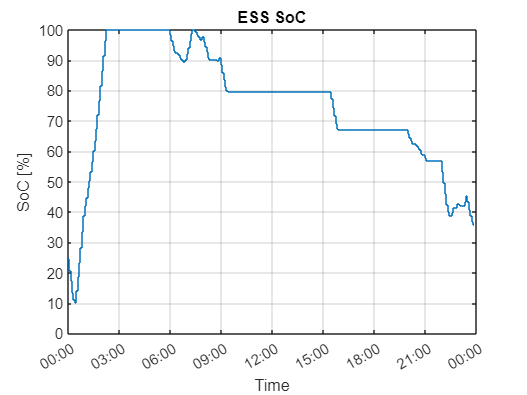

stairs(time, soc)
title('ESS SoC')
datetick('x','HH:MM')
xlabel('Time')
ylabel('SoC [%]')
ylim([0 100])
grid on

Plot ESS power.

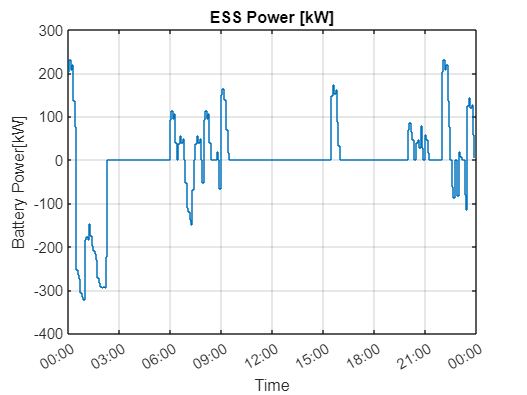

stairs(time, Pbatt)
title('ESS Power [kW]')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Battery Power[kW]')
grid on

Compare grid power.

stairs(time, Pev)
hold on
stairs(time, Pgrid)
legend('without EMS', 'with EMS')
legend('Location', 'southeast')
title('Compare Power Usage')
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
grid on

plot compare graph.

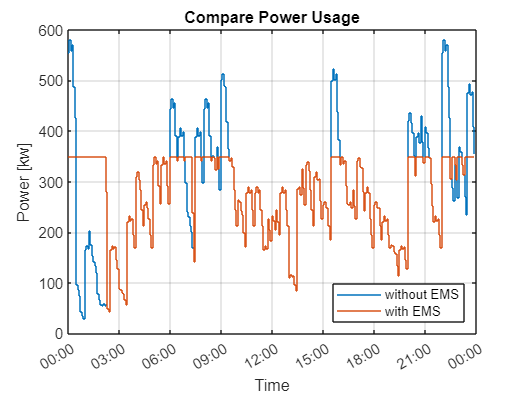

txt = sprintf(['Capacity: %d kWh, Erate: %d\n'...
    'start discharge: %d kW, start charge: %d kW\n' ...
    '[off-peak charging only]'], ...
    capa, Erate, pDscEss, pChgEss);

tiledlayout(2,1)

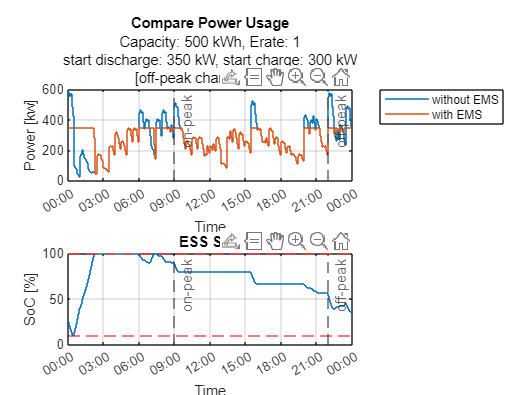

nexttile
stairs(time, Pev)
hold on
stairs(time, Pgrid)
xline(onPeakStr, '--', 'on-peak')
xline(offPeakStr, '--', 'off-peak')
legend('without EMS', 'with EMS')
legend('Location', 'northeastoutside')
title('Compare Power Usage', txt)
datetick('x','HH:MM')
xlabel('Time')
ylabel('Power [kw]')
grid on

nexttile
stairs(time, soc)
xline(onPeakStr, '--', 'on-peak')
xline(offPeakStr, '--', 'off-peak')
yline(soc_max*100, 'r--')
yline(soc_min*100, 'r--')
title('ESS SoC')
datetick('x','HH:MM')
xlabel('Time')
ylabel('SoC [%]')
ylim([0 100])
grid on